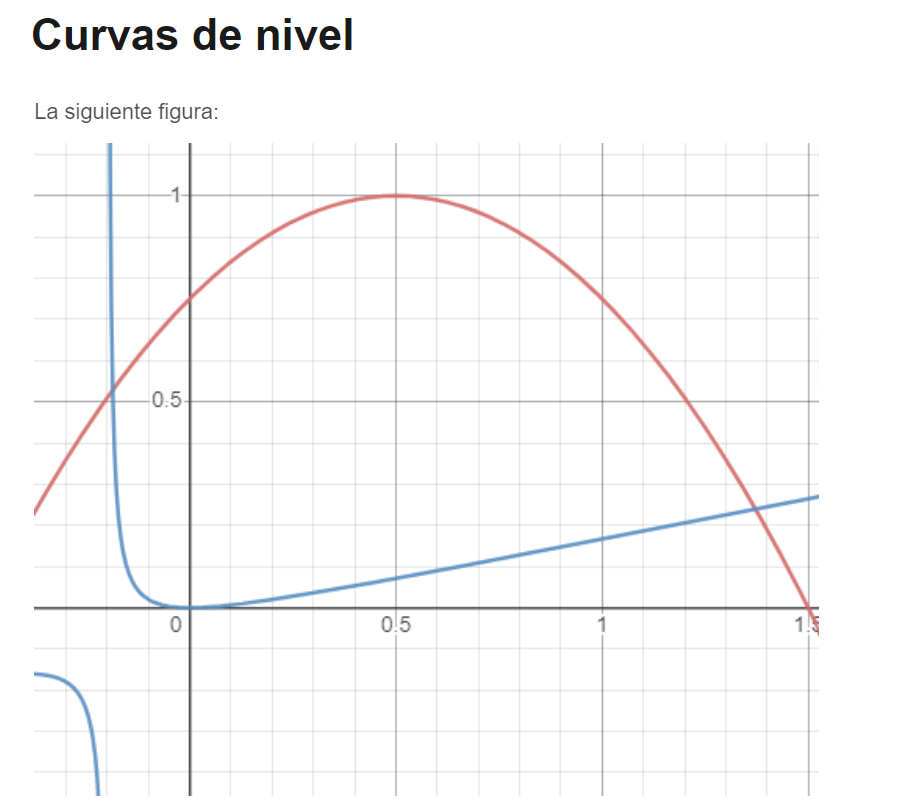

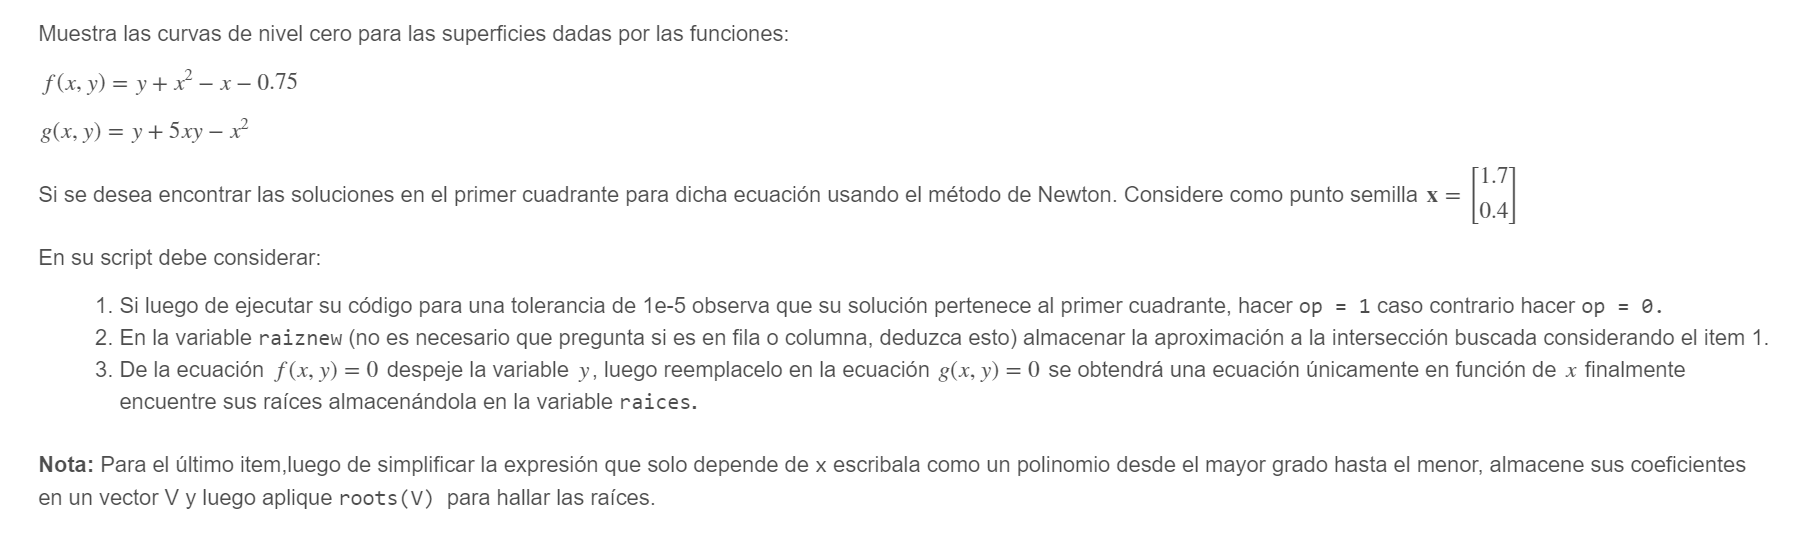

format long
% 1  Curvas de nivel

x0=[1.7 0.4]';
Tol=1e-5
F = @(x, y) [y + x^2 - x - 0.75; y + 5*x*y - x^2]
z=newtons(F,x0,Tol)
% ITEM 1 
op=1
% ITEM 2 
raiznew=[z(end,1) z(end,2)]'
f=@(x)[-(x^2-x-0.75)+5*x*(-x^2+x+0.75)-x^2]
f=[-5 4 4.75 1.5]
raices=sort(roots([-5 3 4.75 0.75]))
function z=newtons(F,x0,Tol)
syms x y
dF = jacobian(F(x,y),[x,y]);
df_fun=matlabFunction(dF);
error=1;
z=[x0' error];
while error>Tol
x1=x0-inv(df_fun(x0(1),x0(2)))*F(x0(1),x0(2));
error=norm(x1-x0,"inf")/norm(x1);
z=[z;x1' error];
x0=x1;
end
end